# Suspension: Analysis

## Design Requirements

Since the distance X1-W is very difficult to measure, and the deformation of the tire (X2-W) is negligible, we will use the distance X1-X2 instead of X1-W as the output in our problem. Keep in mind that this is an approximation.

X1-X2 has an overshoot less than 5% and a settling time shorter than 5 seconds under a step disturbance W.

## Open-Loop Response

M1 = 2500;
M2 = 320;
K1 = 80000;
K2 = 500000;
b1 = 350;
b2 = 15020;

s = tf('s');
% G1: from command u to x1-x2
G1 = ((M1+M2)*s^2+b2*s+K2)/((M1*s^2+b1*s+K1)*(M2*s^2+(b1+b2)*s+(K1+K2))-(b1*s+K1)*(b1*s+K1));
% G2: from disturbance w to x1-2
G2 = (-M1*b2*s^3-M1*K2*s^2)/((M1*s^2+b1*s+K1)*(M2*s^2+(b1+b2)*s+(K1+K2))-(b1*s+K1)*(b1*s+K1));

K_G1 = dcgain(G1);
K_G2 = dcgain(G2);

Notice the DC gain for G1 is very small and DC gain for G2 is actually is zero. THis means when close the feedback loop, the G2 output will be zero in the steady state.

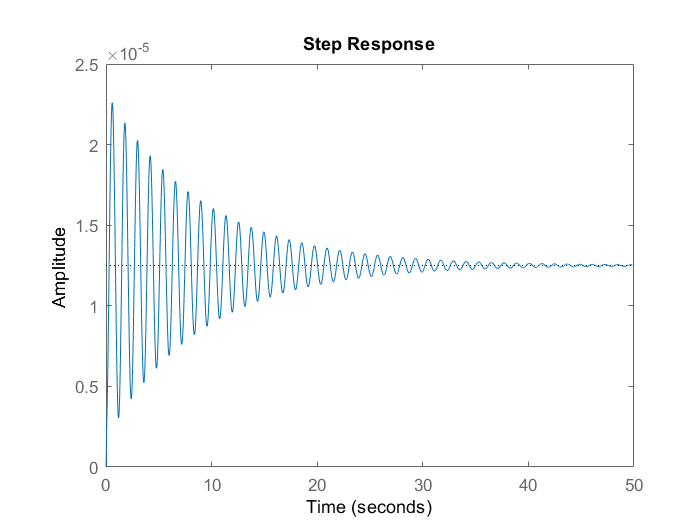

step(G1);

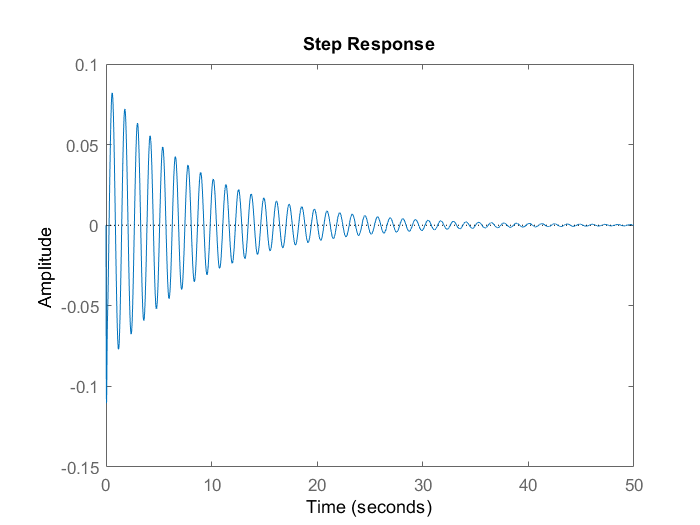

step(0.1*G2);

## System setup

Due to LTI system, the system is as below